# Classifying ECG Signals (Part 1 - CNNs)

We will use deep learning to classify the same ECG dataset using two techniques:

- CNN - Convolutional Neural Network

- LSTM - Long Short-Term Memory Network

## Are You in the Correct Directory?

Your current folder browser should look like this:

% Run this to check
if isfolder('6-AdditionalFiles') && isfolder('6-Wavelets')
    disp('You are in the correct directory. Please continue.')
    addpath(genpath(pwd))
else  
    disp('Please navigate to the proper Directory')
end

You are in the correct directory. Please continue.


## Access and View the Dataset

The networks we train will detect whether an echocardiogram (ECG) signal comes from a heart with: 

- *Normal Sinus Rhythm (NSR)*

- * Arrythmia (ARR) *

- *Congestive Heart Failure (CHF)*

The data are 162 sample signals, sampled at a frequency (Fs) of 128Hz.

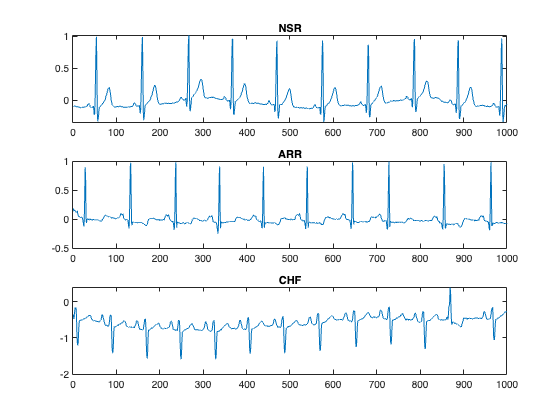

load('ECGData.mat')

subplot(3,1,1); plot(Normal_Sample); title('NSR')
subplot(3,1,2); plot(Arrythmia_Sample); title('ARR')
subplot(3,1,3); plot(HeartFailure_Sample); title('CHF')

## Preprocess Data for CNN

To train a CNN, we first have to convert our signals into images that exhibit unique characteristics for each class. One approach that works for this data set is to convert the data to the time-frequncy spectrum using [continuous wavelet transform](https://www.mathworks.com/help/wavelet/gs/continuous-wavelet-transform-and-scale-based-analysis.html).

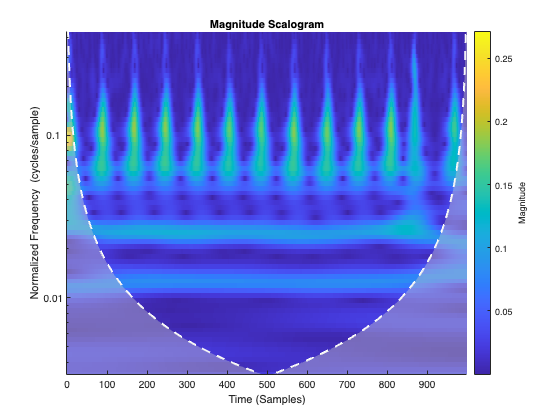

sampleCondition = HeartFailure_Sample;
cwt(sampleCondition)

Open the [`PrepareSignalData.mlx`](matlab:edit('PrepareSignalData.mlx');) file.  This script applies the continuous wavelet transform to all the siganls and saves the images in 'data' folder. This step has already been done, so **you do not run the script.** 

% edit PrepareSignalData.mlx

## View Processed Data

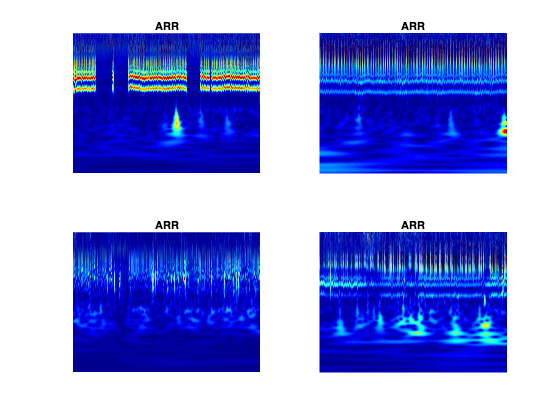

filePath = '6-Wavelets';
imds = imageDatastore(filePath, 'IncludeSubfolders', true, 'LabelSource', 'foldernames');

heartRhythm = "ARR";
idx = find(string(imds.Labels) == heartRhythm);

for i = 1:4
    selectIdx = idx(randi(numel(idx)));
    im = imread(imds.Files{selectIdx});
    subplot(2,2,i)
    imshow(im)
    title(string(imds.Labels(selectIdx)));
end

## Split Data into Training and Test Images

[trainingImages, testImages] = splitEachLabel(imds, 0.8, 'randomize');

## Build CNN with Transfer Learning (programmatically)

net = squeezenet;
layers = net.Layers;

Resize the images to fit the network we will build. 

inputSize = layers(1).InputSize(1:2);
trainingImagesR = augmentedImageDatastore(inputSize, trainingImages);
testImagesR = augmentedImageDatastore(inputSize, testImages);

**Replace Final Layers**

The convolutional layers of the network extract image features that the last learnable layer and the final classification layer use to classify the input image. These two layers, `'conv10'`and `'ClassificationLayer_predictions'` in SqueezeNet, contain information on how to combine the features that the network extracts into class probabilities, a loss value, and predicted labels. To retrain a pretrained network to classify new images, replace these two layers with new layers adapted to the new data set.

Extract the layer graph from the trained network.

lgraph = layerGraph(net); 

Find the names of the two layers to replace. You can do this manually or you can use the supporting function [`findLayersToReplace`](matlab:edit(fullfile(matlabroot,'examples','nnet','main','findLayersToReplace.m'))) to find these layers automatically.

[learnableLayer,classLayer] = findLayersToReplace(lgraph);

In most networks, the last layer with learnable weights is a fully connected layer. In some networks, such as SqueezeNet, the last learnable layer is a 1-by-1 convolutional layer instead. In this case, replace the convolutional layer with a new convolutional layer with the number of filters equal to the number of classes. To learn faster in the new layers than in the transferred layers, increase the `WeightLearnRateFactor` and `BiasLearnRateFactor` values of the convolutional layer.

numClasses = numel(categories(trainingImages.Labels));
newConvLayer =  convolution2dLayer([1, 1],numClasses,'WeightLearnRateFactor',10,'BiasLearnRateFactor',10,"Name",'new_conv');
lgraph = replaceLayer(lgraph,learnableLayer.Name,newConvLayer);

The classification layer specifies the output classes of the network. Replace the classification layer with a new one without class labels. `trainNetwork` automatically sets the output classes of the layer at training time.

newClassificatonLayer = classificationLayer('Name','new_classoutput');
lgraph = replaceLayer(lgraph,'ClassificationLayer_predictions',newClassificatonLayer);

## Set Hyperparameters and Train Network

Use the following training options and save them to variable "opts"

- `InitialLearnRate 0.0001`

- `MaxEpochs        12 `

- `MiniBatchSize    10 `

Training on single CPU.
Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:09 |       50.00% |       0.7233 |      1.0000e-04 |
|       4 |          50 |       00:00:42 |      100.00% |       0.1411 |      1.0000e-04 |
|       8 |         100 |       00:01:06 |      100.00% |       0.0370 |      1.0000e-04 |
|      12 |         150 |       00:01:34 |      100.00% |       0.0618 |      1.0000e-04 |
|      12 |         156 |       00:01:37 |      100.00% |       0.0299 |      1.0000e-04 |
|========================================================================================|
Training finished: Max epoc

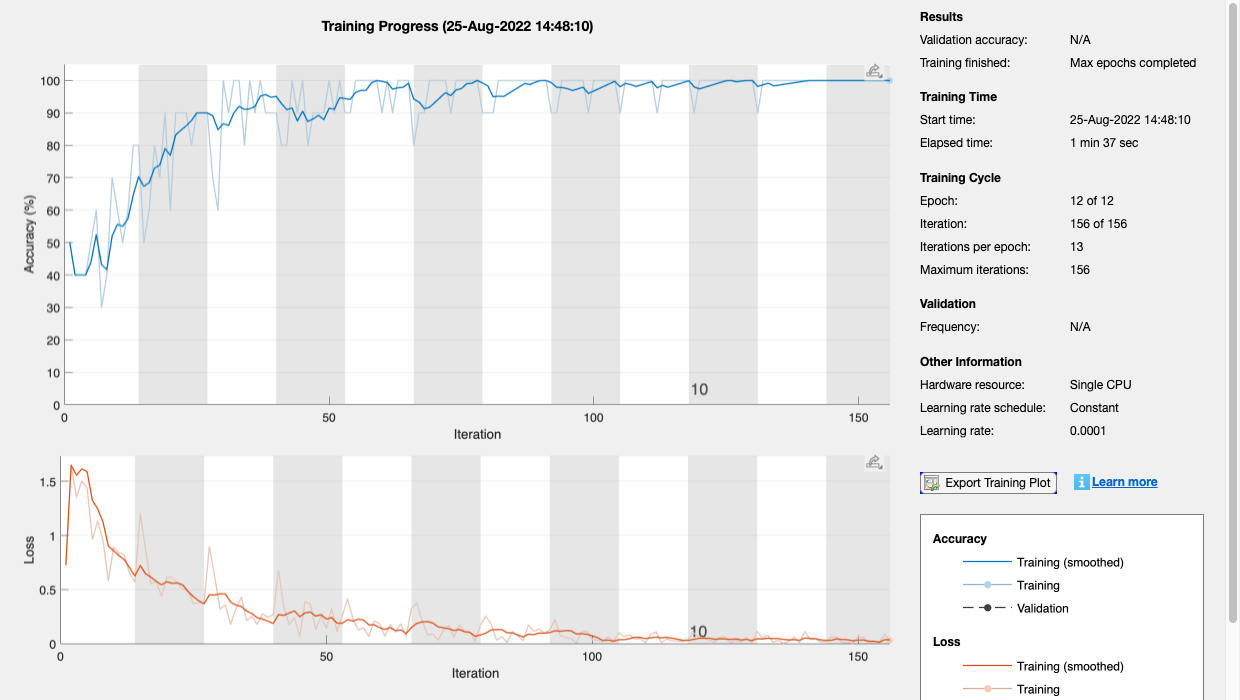

opts = trainingOptions('sgdm', 'InitialLearnRate', 0.0001, ...
        'MaxEpochs', 12, 'MiniBatchSize', 10, ...
        'Plots', 'training-progress');
    
ECGNet = trainNetwork(trainingImagesR, lgraph, opts);

## Test the Network

labels = classify(ECGNet, testImagesR);
accuracy = sum(labels == testImages.Labels)*100 / numel(labels)

accuracy = 93.7500

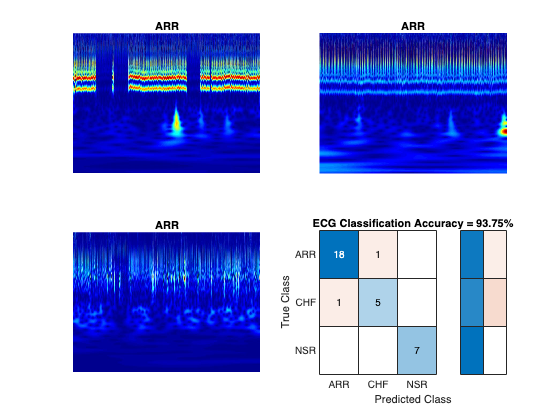

cm = confusionchart(labels, testImages.Labels);
figure
cm.RowSummary = 'row-normalized';
cm.Title = ['ECG Classification Accuracy = ' num2str(accuracy) '%'];

## Classify Signals using LSTM

Try out part 2 of the exercise.

edit Solution_ECG_LSTM.mlx

*Copyright 2022 The MathWorks, Inc.*